## **Esercizio 2**

clear variables; close all; clc;

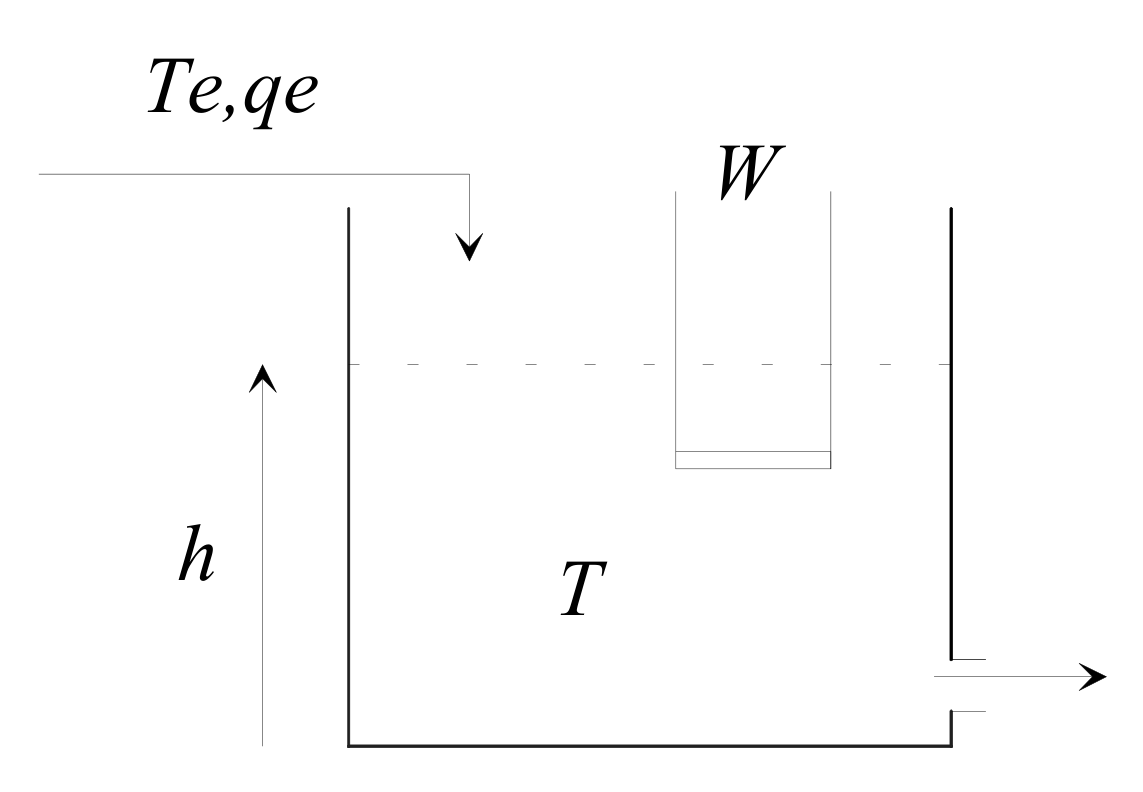

### **Il sistema termico-idraulico riportato in figura è descritto dal modello:**

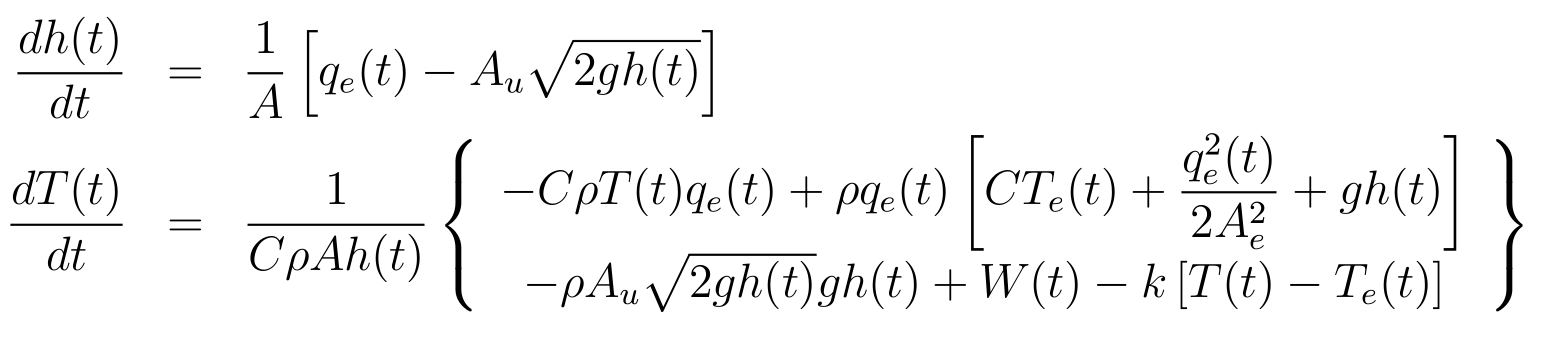

% Sezione del serbatoio [m^2]
A = 0.08;

% Sezione condotto d'ingresso [m^2]
A_e = 1e-4;

% Sezione condotto d'uscita [m^2]
A_u = 2.5e-5;

% Calore specifico del liquido [J/(C * kg)]
C = 4184;

% Densità del liquido [kg/m^3]
rho = 1000;

% Accelerazione di gravità [m/s^2]
g = 9.8;

% Coefficiente di scambio [W/K]
k = 10;

### **1) Punto di equilibrio**

**Si verifichi che i valori di equilibrio siano corretti (salvo approssimazioni).**

% ingresso di equilibrio: portata liquido in ingresso al serbatoio [m^3]
q_e = 4.95e-5;

% ingresso di equilibrio: potenza [W]
W = 1035;

% disturbo di equilibrio: temperatura esterna [C]
T_e = 20;

% stato di equilibrio: altezza liquido nel serbatoio [m]
h = q_e^2 / (2*g*A_u^2)

h = 0.2000

% verifica a posteriori punto di equilibrio
% abs(A_u*sqrt(2*g*h) - q_e) <= 1e-8

% stato di equilibrio: temperatura liquido nel serbatoio [C]
T = (rho*q_e*(C*T_e+(q_e^2/(2*A_e^2))+g*h) - rho*A_u*sqrt(2*g*h)*g*h + W + k*T_e)/(C*rho*q_e + k)

T = 24.7672

% verifica a posteriori punto di equilibrio
% abs(-C*rho*T*q_e + rho*q_e*(C*T_e+(q_e^2/(2*A_e^2))+g*h) - rho*A_u*sqrt(2*g*h)*g*h + W - k*(T-T_e)) <= 1e-8

### **2) Linearizzazione nel punto di equilibrio**

dhh = -g*A_u / (A*sqrt(2*g*h));
dh1 = 1/A;
dh2 = 0;
dh3 = 0;
dTT = -(C*rho*q_e + k) / (C*rho*A*h);
dT1 = (-C*T + C*T_e + 3/2*(q_e/A_e)^2 + g*h)/(C*A*h);
dT2 = 1/(C*rho*A*h);
dT3 = (C*rho*q_e + k) / (C*rho*A*h);
s = tf('s');
G11 = dh1 / (s - dhh);
G12 = dh2 / (s - dhh);
M13 = dh3 / (s - dhh);
G21 = dT1 / (s - dTT);
G22 = dT2 / (s - dTT);
M23 = dT3 / (s - dTT);
G = [G11 G12; G21 G22];
M = [M13; M23];

% calcolo simbolico con matematica: risultati
% nablaT_T = -54277/16736000;
% nablaT_Te = 54277/16736000;
% nablaT_Qe = -1673554917/5355520;
% nablaT_W = 1/66944;
% s = tf('s');
% tfTW = tf(nablaT_W/(-nablaT_T), [1/(-nablaT_T)  1])
% tfTQe = tf(nablaT_Qe/(-nablaT_T), [1/(-nablaT_T)  1])
% tfTTe = tf(nablaT_Te/(-nablaT_T), [1/(-nablaT_T)  1])
% dcgain(tfTQe)*q_e + dcgain(tfTW)*W + dcgain(tfTTe)*T_e
% verifica a posteriori equilibrio ?
% dcgain(G) * [q_e; W] + dcgain(M) * T_e

### **2) Matrice dei guadagni relativi**

**Si calcoli la matrice dei guadagni relativi e si giustifichi il risultato.**

G_0 = dcgain(G);
G_dcgain_rel = G_0 .* (inv(G_0))'

G_dcgain_rel =     1.0000         0
   -0.0000    1.0000


### **3) Progettazione regolatore di disaccopiamento**

** Si elimini l’effetto di q_e su T mediante uno schema di disaccoppiamento.**

D11 = 1;
D22 = 1;
D12 = -G12/G11;
D21 = -G21/G22;
D = minreal([D11 D12; D21 D22])


D =
 
  From input 1 to output...
   1:  1
 
   2:  1.994e07
 
  From input 2 to output...
   1:  0
 
   2:  1
 
Static gain.



Gt = G*D


Gt =
 
  From input 1 to output...
           12.5
   1:  ------------
       s + 0.001547
 
   2:  0
 
  From input 2 to output...
   1:  0
 
        1.494e-05
   2:  ------------
       s + 0.003243
 
Continuous-time transfer function.



### **4) Progettazione regolatori PI**

**Si progettino due PI per gli anelli disaccoppiati facendo in modo che la velocità di risposta dei sistemi reazionati sia all’incirca doppia di quella dei sistemi in anello aperto.**

g11 = G_0(1,1);
g22 = G_0(2,2);
mu1 = -2 * pole(G11) / g11;
mu2 = -2 * pole(G22) / g22;

R1 = mu1 * (1-s/pole(G11))/s;
L1 = g11*mu1/s


L1 =
 
  0.003093
  --------
     s
 
Continuous-time transfer function.



wc1 = g11 * mu1

wc1 = 0.0031

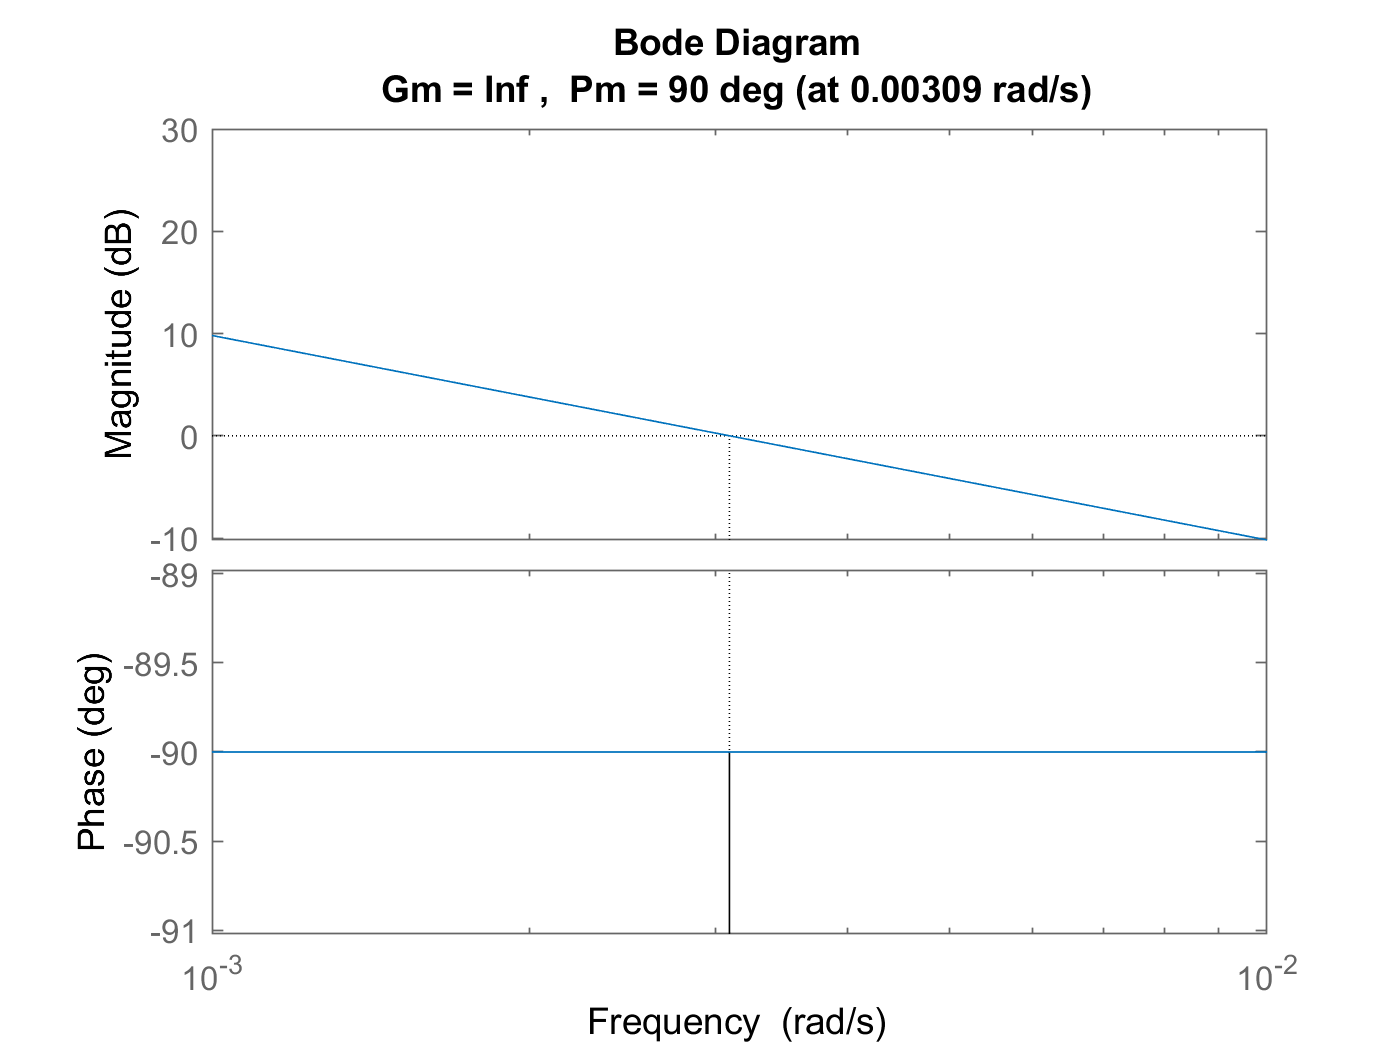

margin(L1)

R2 = mu2 * (1-s/pole(G22))/s;
L2 = g22*mu2/s


L2 =
 
  0.006486
  --------
     s
 
Continuous-time transfer function.



wc2 = g22 * mu2

wc2 = 0.0065

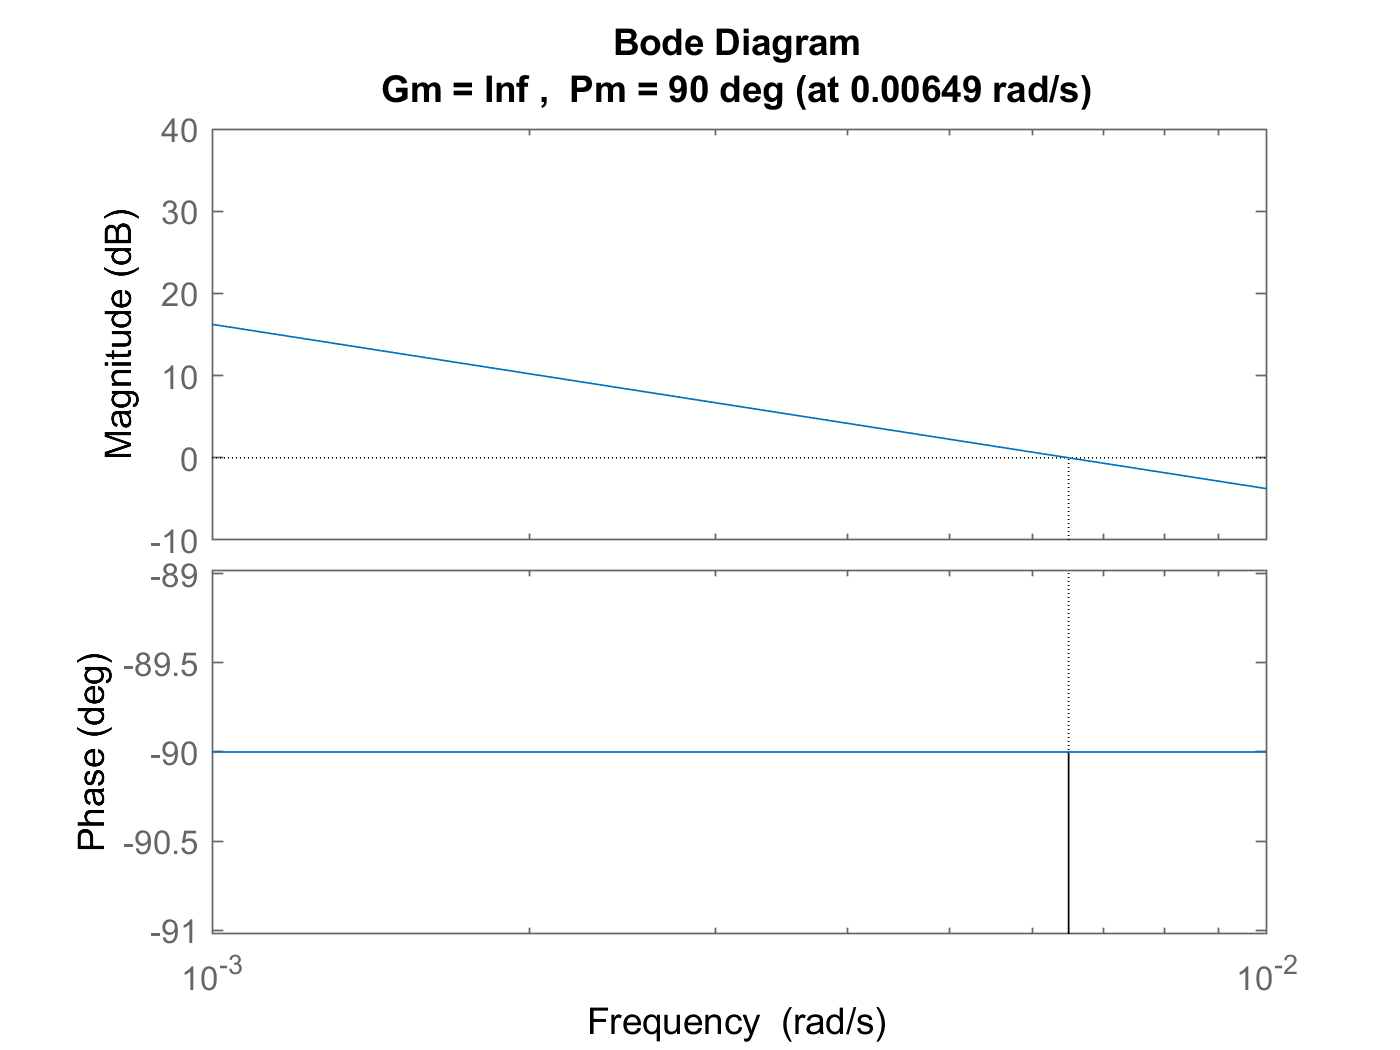

margin(L2)

tG11 = stepinfo(G11);
tG11 = tG11.SettlingTime

tG11 = 2.5293e+03

tF1 = stepinfo(L1/(1+L1));
tF1 = tF1.SettlingTime

tF1 = 1.2646e+03

tG22 = stepinfo(G22);
tG22 = tG22.SettlingTime

tG22 = 1.2064e+03

tF2 = stepinfo(L2/(1+L2));
tF2 = tF2.SettlingTime

tF2 = 603.1943

### **7) Progettazione compensatore del disturbo**

** Si progetti un compensatore del disturbo.**

M2 = minreal(-M23/G22)


M2 =
 
  -217.1
 
Static gain.

